# **第七章**

7.21 利用matlab工具箱函数，分别画出长度为15的矩形窗，汉宁窗，汉明窗和布莱克曼窗的幅频特性(DB)曲线，观察他们的主要参数(主瓣宽度，过渡带宽度，旁瓣峰值服务)的差别。

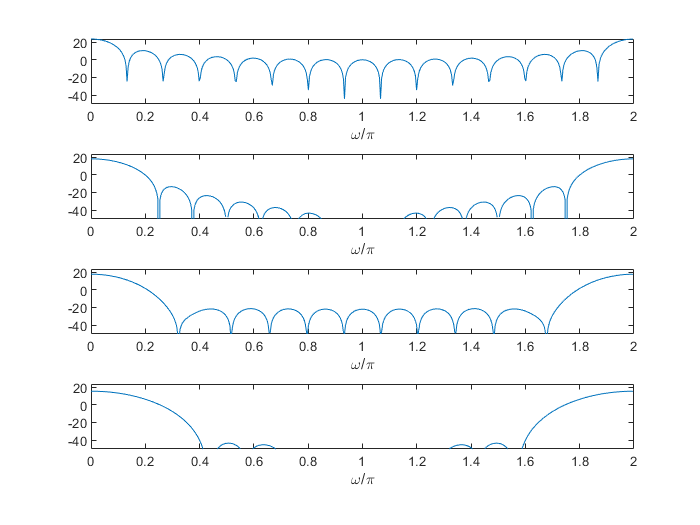

w1=boxcar(15);
w2=hanning(15);
w3=hamming(15);
w4=blackman(15);
[H1,wx1]=freqz(w1,1,'whole');
[H2,wx2]=freqz(w2,1,'whole');
[H3,wx3]=freqz(w3,1,'whole');
[H4,wx4]=freqz(w4,1,'whole');
figure(1)
ax1=subplot(4,1,1);
plot(wx1/pi,20.*log10(abs(H1)));
xlabel('\omega/\pi');
ax2=subplot(4,1,2);
plot(wx2/pi,20.*log10(abs(H2)));
xlabel('\omega/\pi');
ax3=subplot(4,1,3);
plot(wx3/pi,20.*log10(abs(H3)));
xlabel('\omega/\pi');
ax4=subplot(4,1,4);
plot(wx4/pi,20.*log10(abs(H4)));
xlabel('\omega/\pi');
linkaxes([ax1 ax2 ax3 ax4],'y');

7.30 利用matlab工具箱函数并编写程序，采用频率采样法设计一个严格线性相位FIR数字低通滤波器，要求通带截止频率$\omega_{\mathrm{p}} =\frac{\pi }{3}rad\$过渡带宽度$\Delta \mathrm{B}\le \frac{\pi }{16}rad\$，阻带最小衰减$\alpha_{\mathrm{s}} =40dB$，允许在过渡带上设置采样点。画出所设计滤波器的单位脉冲响应$\mathrm{h}\left(\mathrm{n}\right)$的波形以及幅频响应特性曲线。

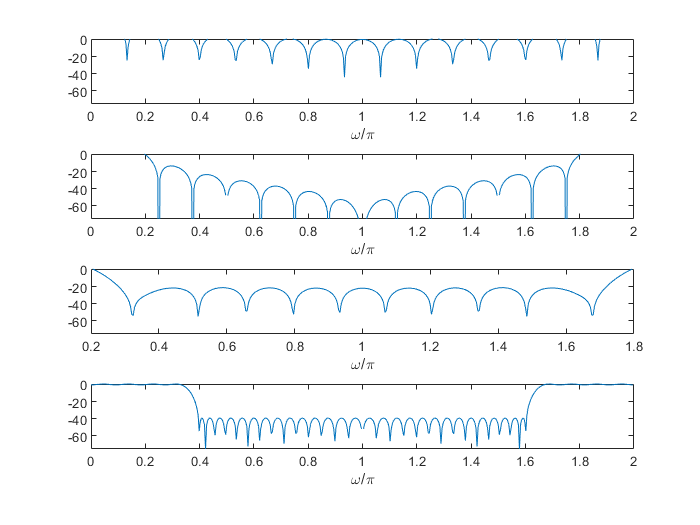

f=[1/3,1/3+1/16];
m=[1,0];
Rp=1;Rs=40;
d1=(10^(Rp/20)-1)/(10^(Rp/20)+1);
d2=10^(-Rs/20);
rip=[d1,d2];
[M,f0,m0,w]=remezord(f,m,rip);
hn=remez(M,f0,m0,w);
[Hh,wxh]=freqz(hn,1,'whole');
figure(3)
plot(wxh/pi,20.*log10(abs(Hh)));
xlabel('\omega/\pi');